# Secondary AtmoData Processing

Brendan Apple

Creates the most relevant graphs from data collected by the Atmospheric Data Sensor on Cardinal, which was created by NCSSM's High Powered Rocketry Team.

warning off
clear,clc,close

#### Loads in All the Data

AtmoTable = readtable("Datalog.csv")

AtmoTable = 5741×37 table
    Time    Min    Sec    MS     Temperature    Humidity    Heater    TVOC    CO2     H2      Ethanol    Orientation_X    Orientation_Y    Orientation_Z    Gyrometer_X    Gyrometer_Y    Gyrometer_Z    Gyrometer_Total    Linear_X    Linear_Y    Linear_Z    Linear_Total    Magnetic_X    Magnetic_Y    Magnetic_Z    Magnetic_Total    Acceleration_X    Acceleration_Y    Acceleration_Z    Acceleration_Total    Gravity_X    Gravity_Y

## Analysis

`/* Board layout:`

`            +----------+`

`            |         *| RST   PITCH  ROLL  HEADING`

`        ADR |*        *| SCL`

`        INT |*        *| SDA     ^            /->`

`        PS1 |*        *| GND     |            |`

`        PS0 |*        *| 3VO     Y    Z-->    \-X`

`            |         *| VIN`

`            +----------+`

`      */`

#### Temperature (C) and Humidity (Relative %) vs Time

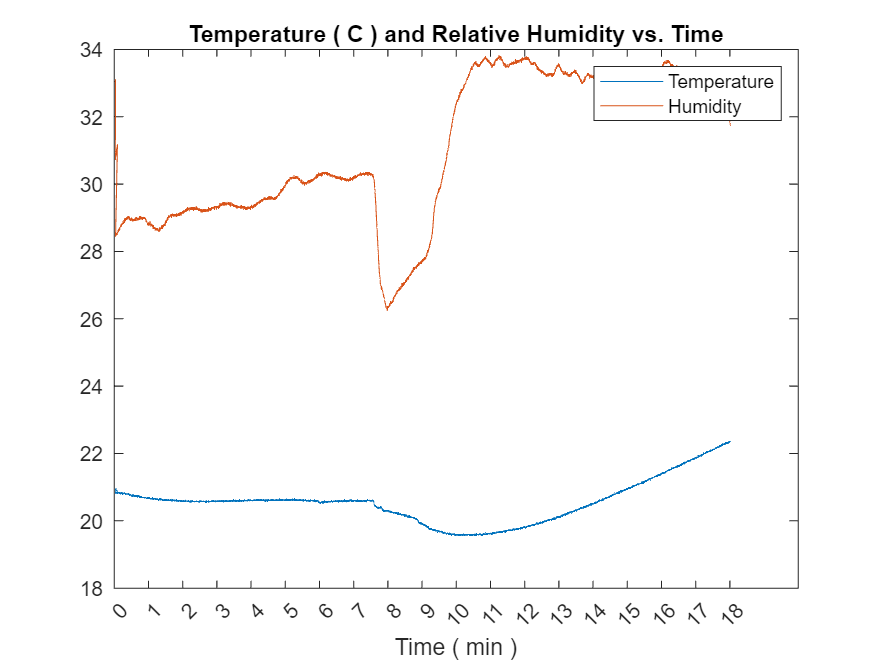

TempHumidPlot = plot(AtmoTable, "Time", ["Temperature", "Humidity"]);
title("Temperature ( C ) and Relative Humidity vs. Time")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5740, "Time"}])
legend

MaxTemp = max(AtmoTable.("Temperature"))

MaxTemp = 22.3700

MeanTemp = mean(AtmoTable.("Temperature"))

MeanTemp = 20.5544

MedianTemp = median(AtmoTable.("Temperature"))

MedianTemp = 20.5900

ModeTemp = mode(AtmoTable.("Temperature"))

ModeTemp = 20.5900

MinTemp = min(AtmoTable.("Temperature"))

MinTemp = 19.5600

STDTemp = std(AtmoTable.("Temperature"))

STDTemp = 0.6338

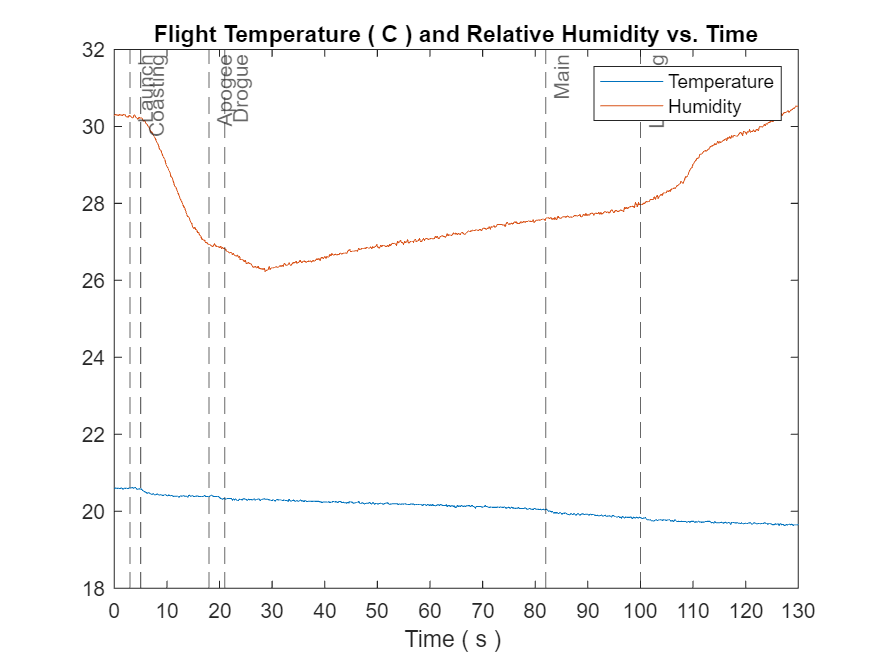

ZoomTempHumidPlot = plot(AtmoTable, "Time", ["Temperature", "Humidity"]);
title("Flight Temperature ( C ) and Relative Humidity vs. Time")
xlabel("Time ( s ) ")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

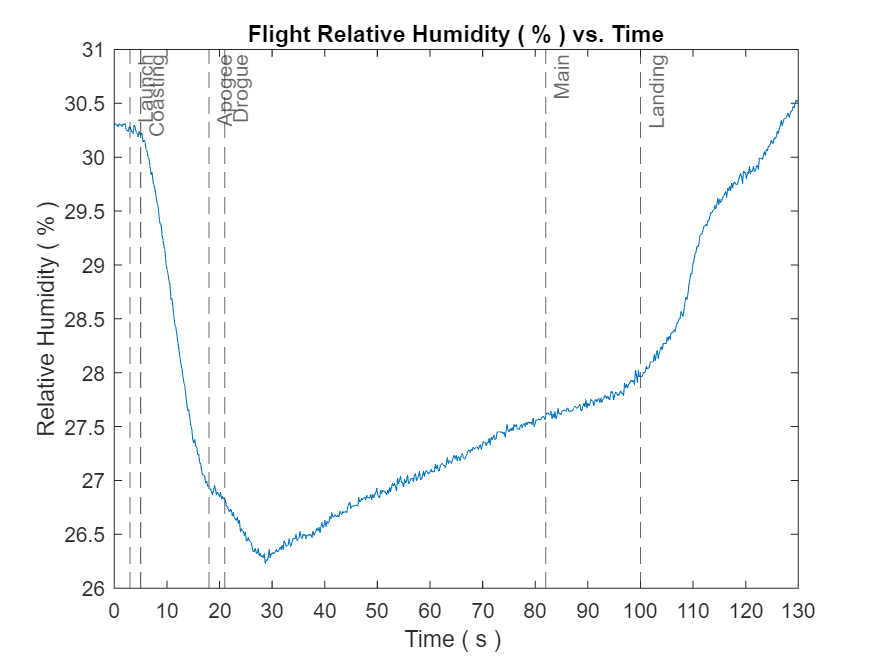

ZoomHumidPlot = plot(AtmoTable, "Time", "Humidity");
title("Flight Relative Humidity ( % ) vs. Time")
ylabel("Relative Humidity ( % )")
xlabel("Time ( s ) ")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])

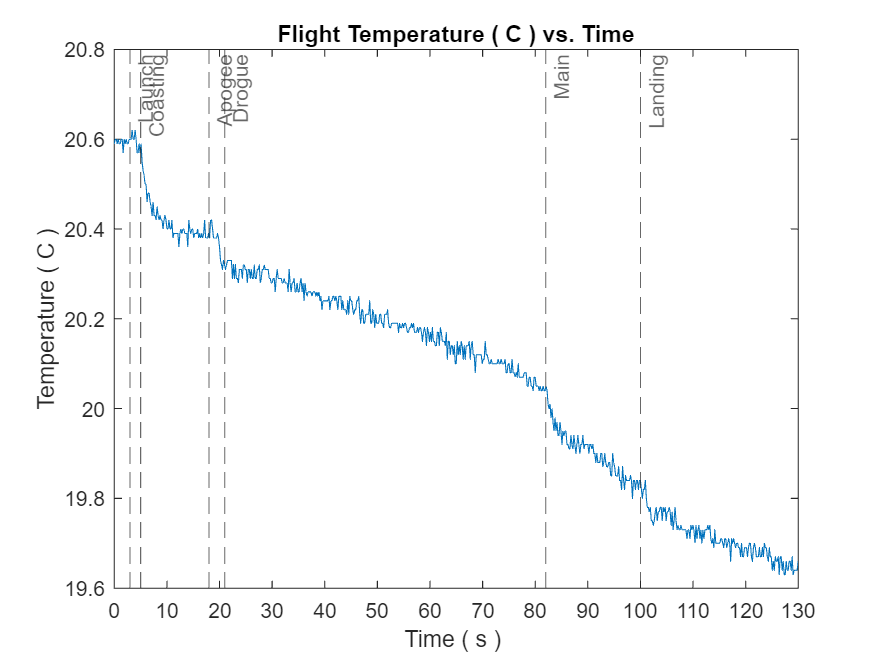

ZoomTempPlot = plot(AtmoTable, "Time", "Temperature");
title("Flight Temperature ( C ) vs. Time")
ylabel("Temperature ( C )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xlabel("Time ( s ) ")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])

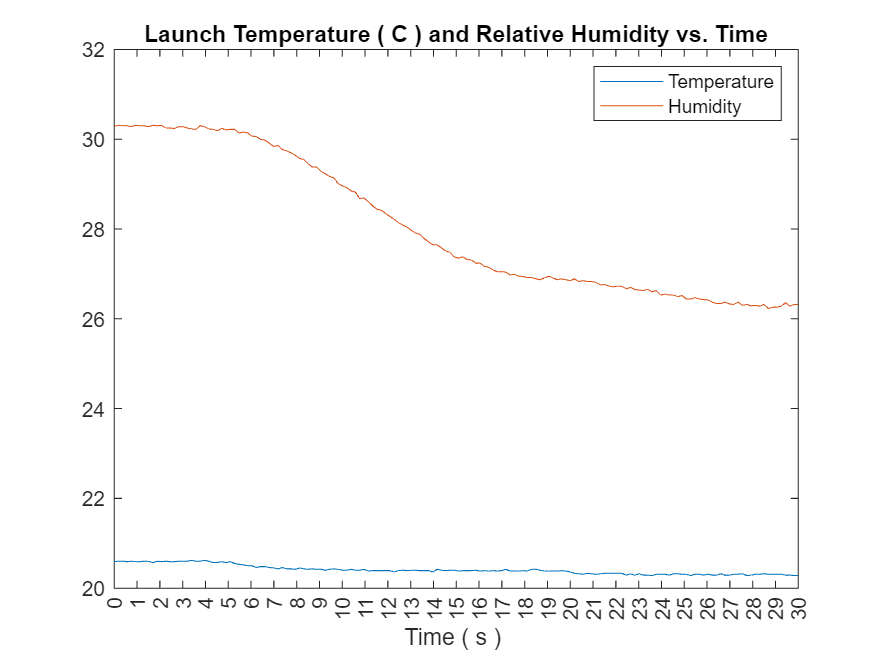

LaunchTempHumidPlot = plot(AtmoTable, "Time", ["Temperature", "Humidity"]);
title("Launch Temperature ( C ) and Relative Humidity vs. Time")
xlabel("Time ( s ) ")
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

#### TVOC (ppb) and CO2 (ppm) vs Time

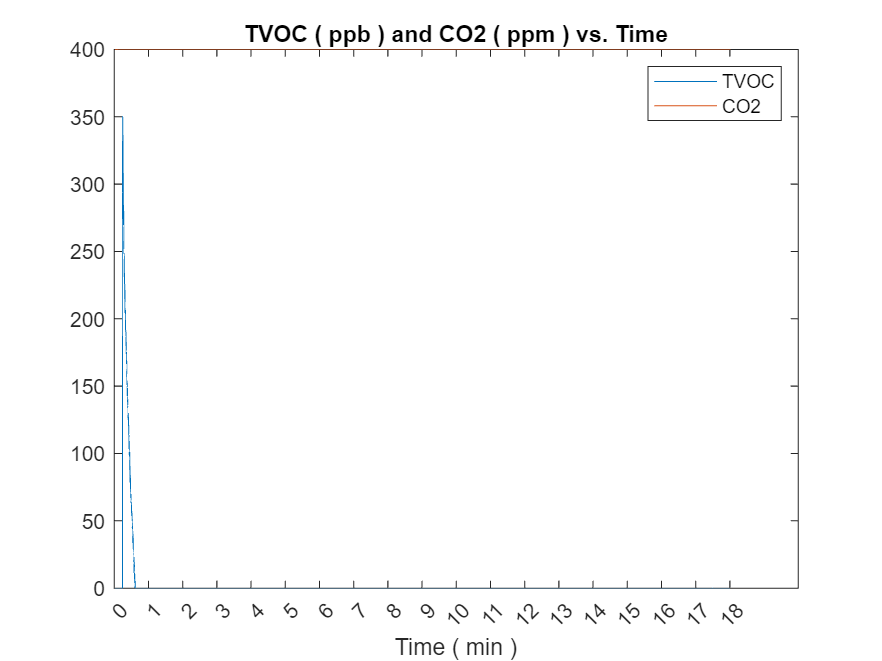

TVOCeCO2Plot = plot(AtmoTable, "Time", ["TVOC", "CO2"]);
title("TVOC ( ppb ) and CO2 ( ppm ) vs. Time")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

#### H2 and Ethanol vs Time

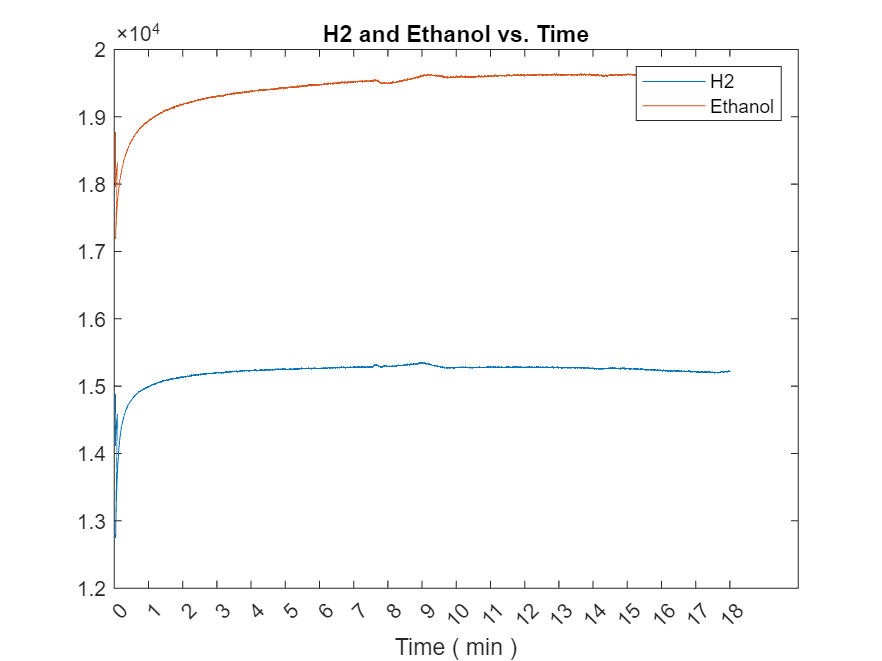

ZoomTVOCeCO2Plot = plot(AtmoTable, "Time", ["H2", "Ethanol"]);
title("H2 and Ethanol vs. Time")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

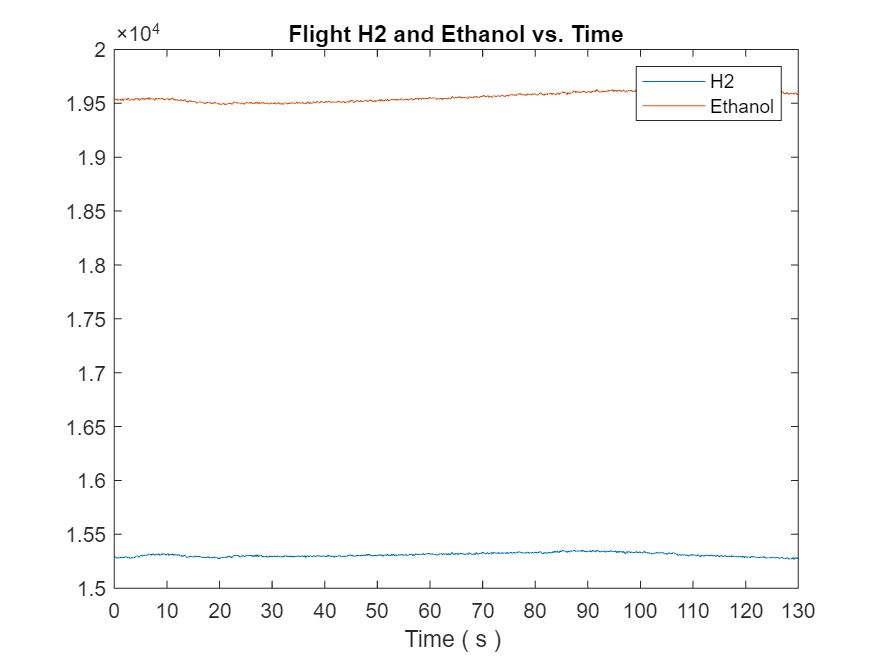

EthanolH2Plot = plot(AtmoTable, "Time", ["H2", "Ethanol"]);
title("Flight H2 and Ethanol vs. Time")
xlabel("Time ( s ) ")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

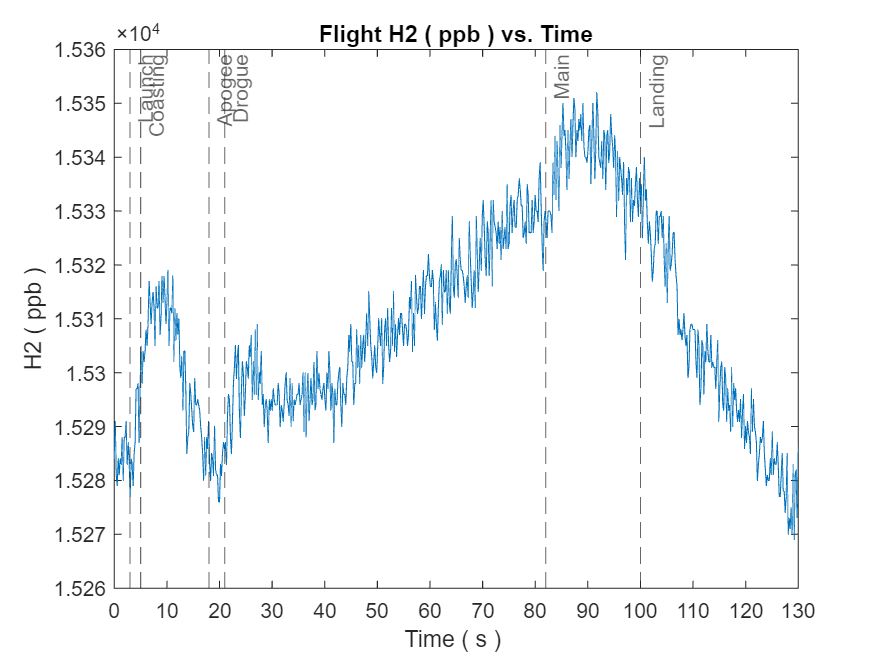

ZoomH2Plot = plot(AtmoTable, "Time", "H2");
title("Flight H2 ( ppb ) vs. Time")
xlabel("Time ( s ) ")
ylabel("H2 ( ppb )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])

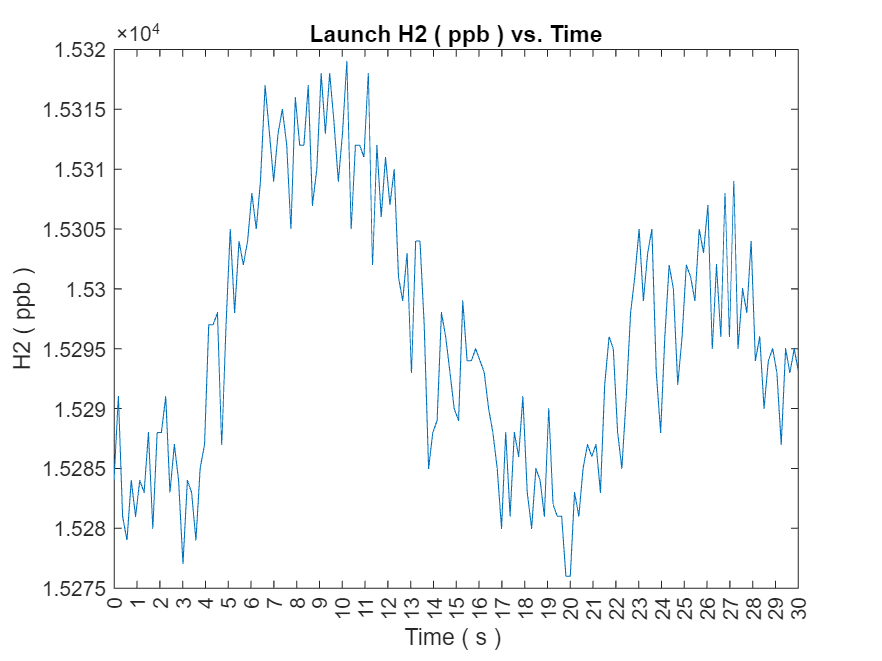

LaunchH2Plot = plot(AtmoTable, "Time", "H2");
title("Launch H2 ( ppb ) vs. Time")
xlabel("Time ( s ) ")
ylabel("H2 ( ppb )")
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:580000])

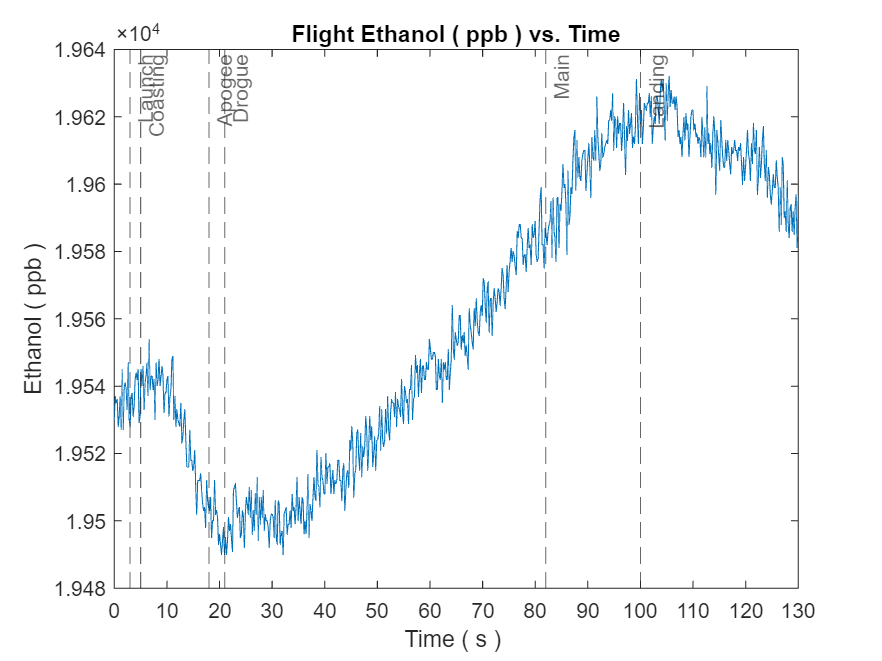

ZoomEthanolPlot = plot(AtmoTable, "Time", "Ethanol");
title("Flight Ethanol ( ppb ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Ethanol ( ppb )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])

#### Orientation (degrees) vs Time

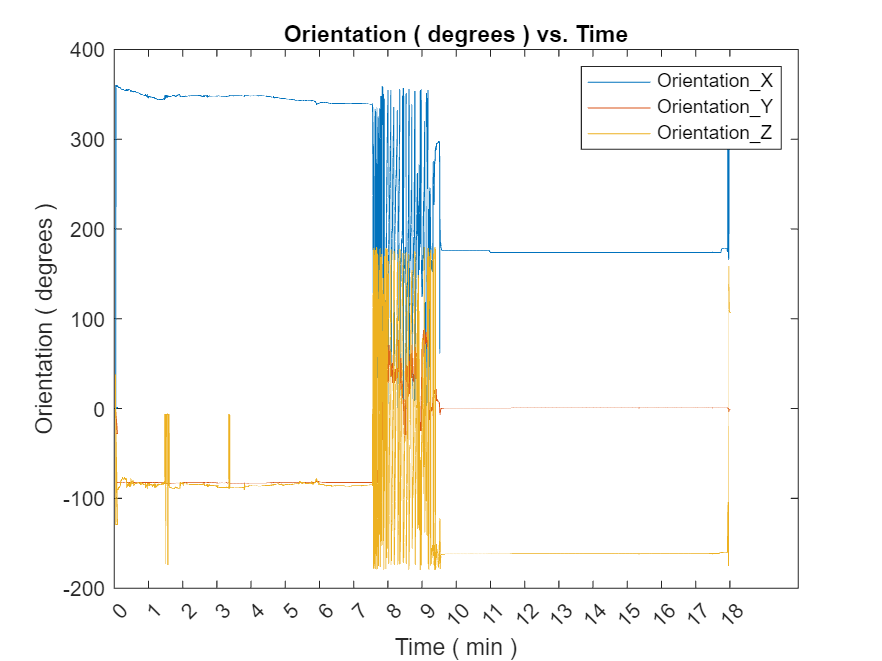

OrientPlot = plot(AtmoTable, "Time", ["Orientation_X", "Orientation_Y", "Orientation_Z"]);
title("Orientation ( degrees ) vs. Time")
ylabel("Orientation ( degrees )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

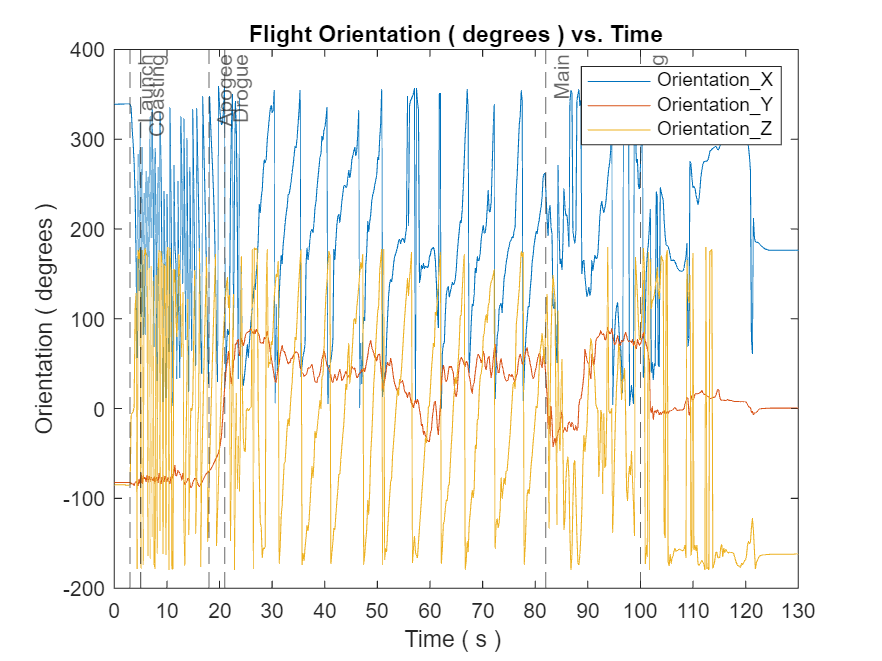

ZoomOrientPlot = plot(AtmoTable, "Time", ["Orientation_X", "Orientation_Y", "Orientation_Z"]);
title("Flight Orientation ( degrees ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Orientation ( degrees )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

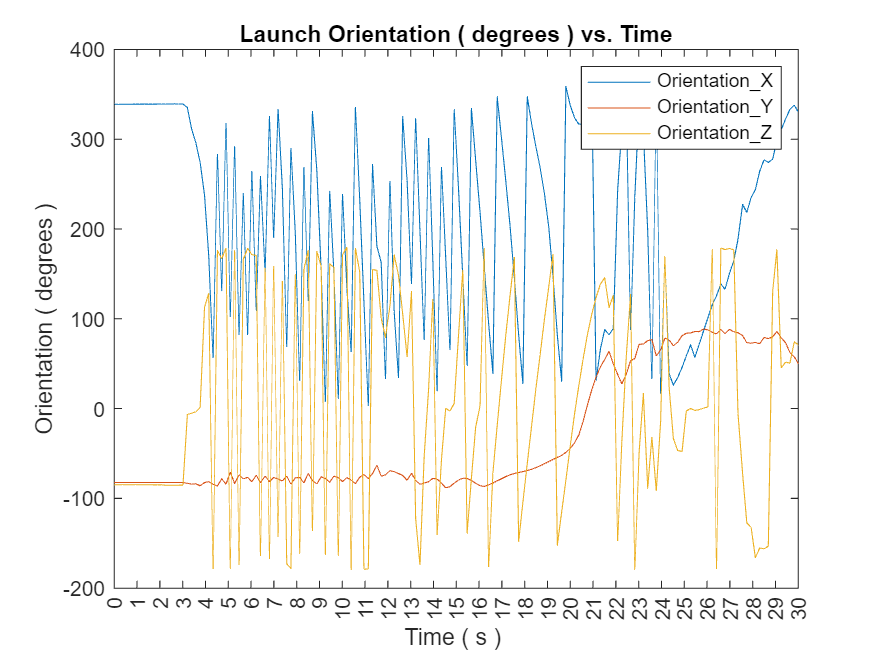

LaunchOrientPlot = plot(AtmoTable, "Time", ["Orientation_X", "Orientation_Y", "Orientation_Z"]);
title("Launch Orientation ( degrees ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Orientation ( degrees )")
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

#### Gyroscope (rad/s) vs Time

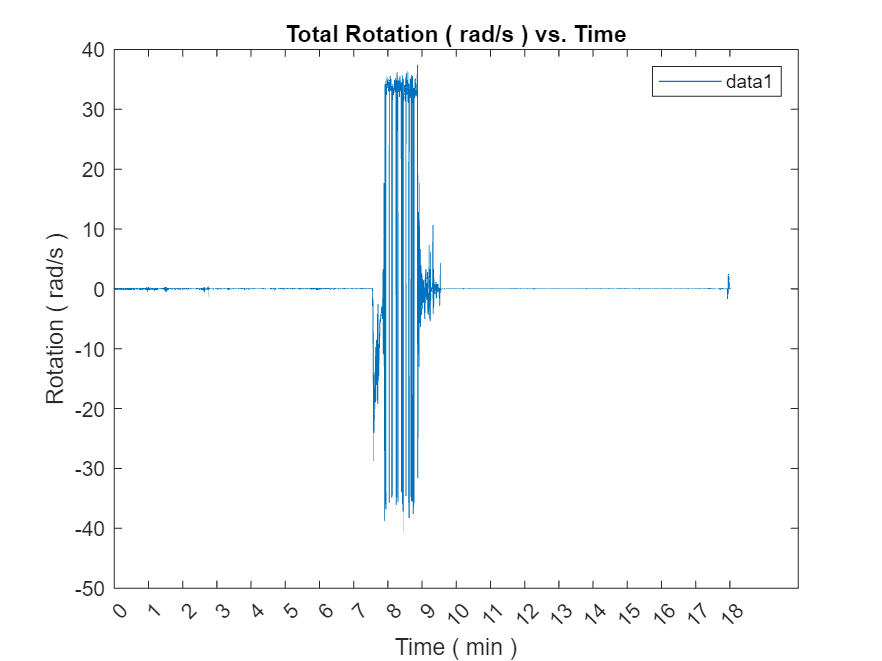

GyroTotalPlot = plot(AtmoTable, "Time", "Gyrometer_Total");
title("Total Rotation ( rad/s ) vs. Time")
ylabel("Rotation ( rad/s )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

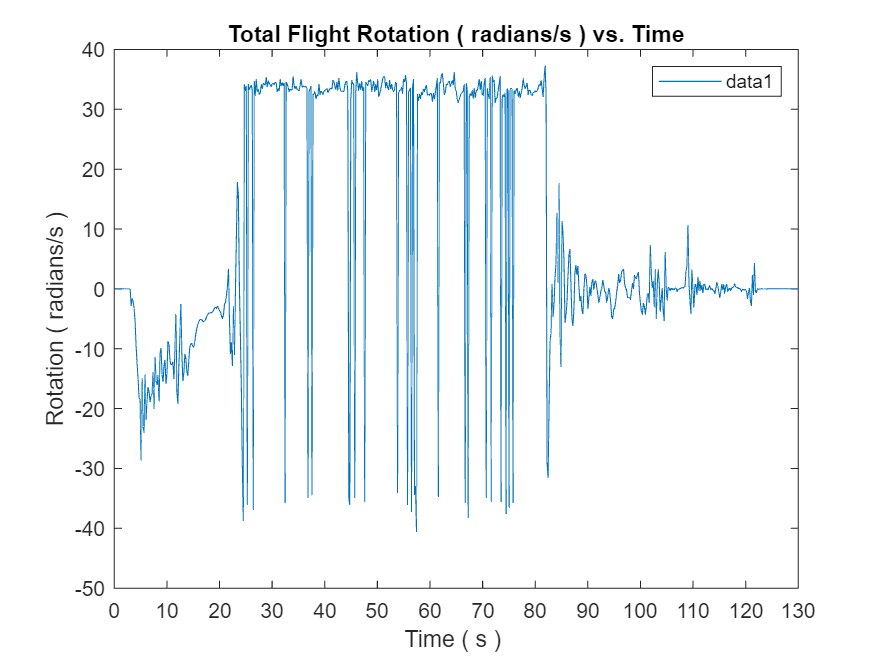

ZoomGyroTotalPlot = plot(AtmoTable, "Time", "Gyrometer_Total");
title("Total Flight Rotation ( radians/s ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Rotation ( radians/s )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

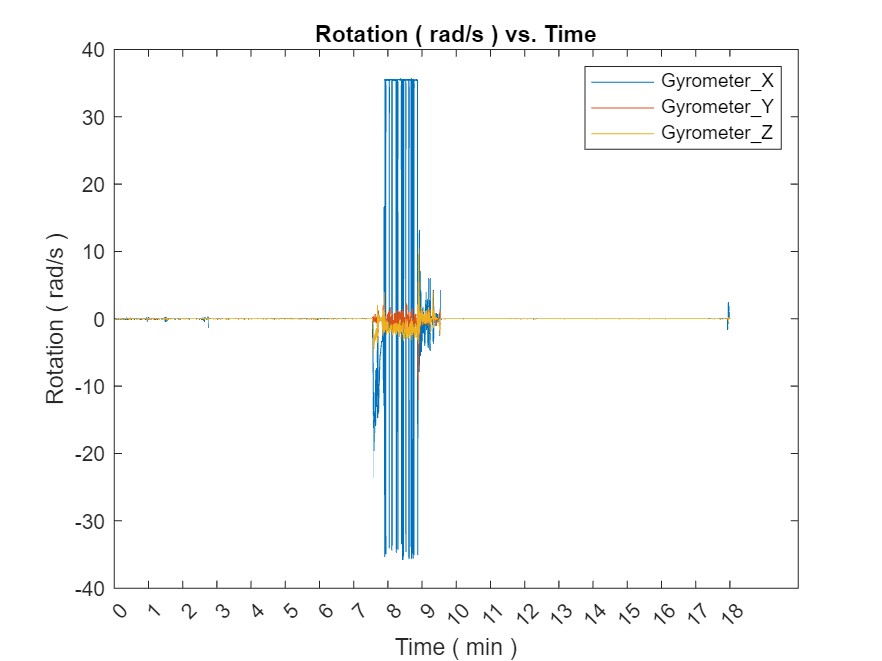

GyroPlot = plot(AtmoTable, "Time", ["Gyrometer_X", "Gyrometer_Y", "Gyrometer_Z"]);
title("Rotation ( rad/s ) vs. Time")
ylabel("Rotation ( rad/s )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

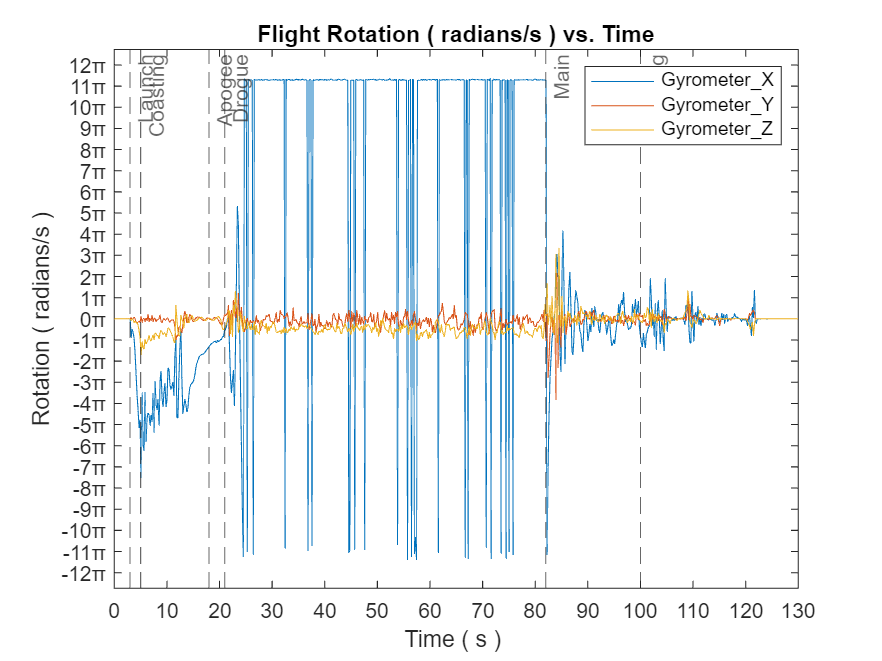

ZoomGyroPlot = plot(AtmoTable, "Time", ["Gyrometer_X", "Gyrometer_Y", "Gyrometer_Z"]);
title("Flight Rotation ( radians/s ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Rotation ( radians/s )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
yticklabels([-13:13] + "π")
yticks(-13*pi:pi:13*pi)
xticks([450000:10000:580000])
legend

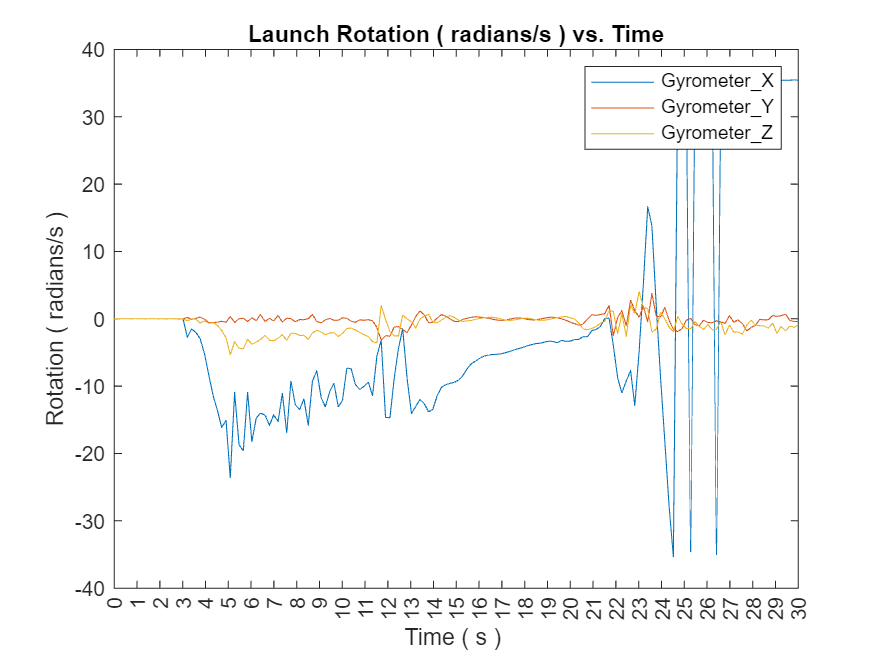

LauncgGyroPlot = plot(AtmoTable, "Time", ["Gyrometer_X", "Gyrometer_Y", "Gyrometer_Z"]);
title("Launch Rotation ( radians/s ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Rotation ( radians/s )")
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

#### Linear Acceleration (m/s^2) vs Time

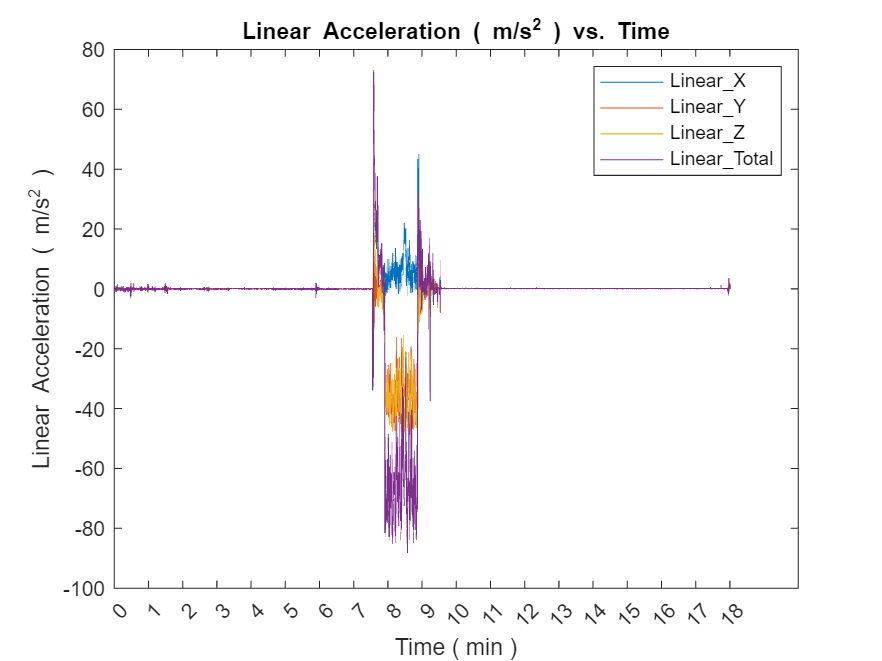

LinearPlot = plot(AtmoTable, "Time", ["Linear_X", "Linear_Y", "Linear_Z", "Linear_Total"]);
title("Linear Acceleration ( m/s^2 ) vs. Time")
ylabel("Linear Acceleration ( m/s^2 )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

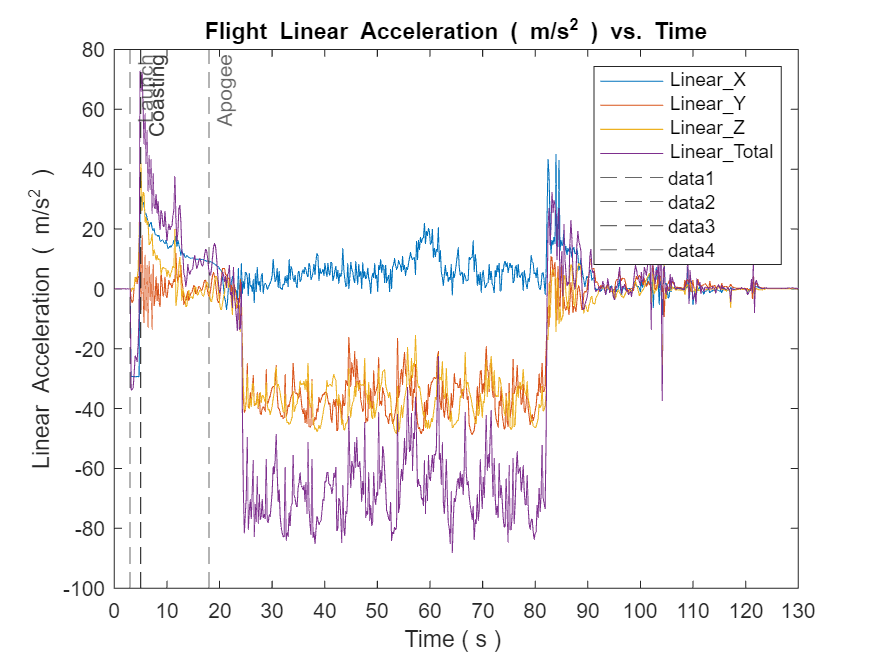

ZoomLinearPlot = plot(AtmoTable, "Time", ["Linear_X", "Linear_Y", "Linear_Z", "Linear_Total"]);
title("Flight Linear Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Linear Acceleration ( m/s^2 )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

#### Magnetism (uT) vs Time

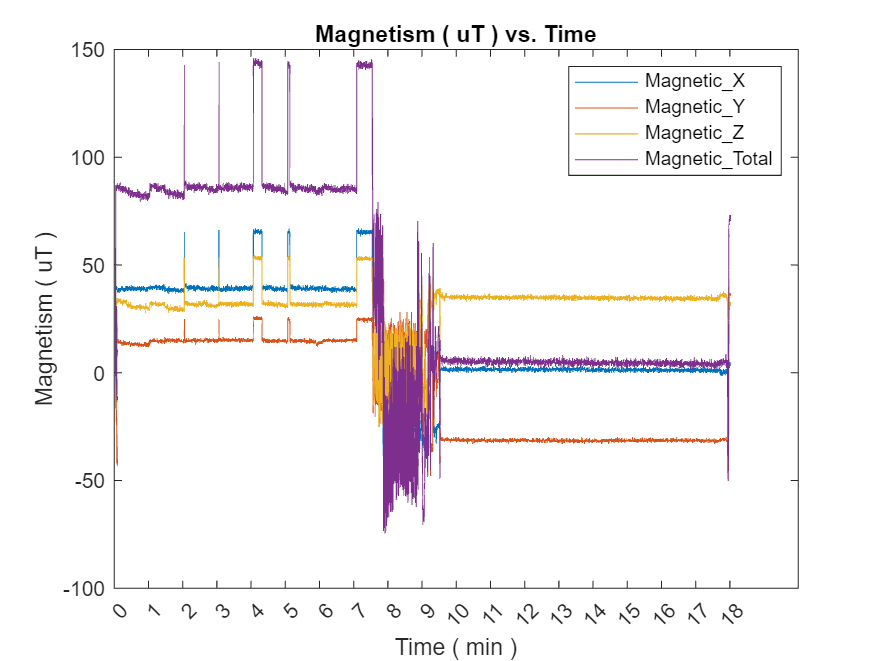

MagnetPlot = plot(AtmoTable, "Time", ["Magnetic_X", "Magnetic_Y", "Magnetic_Z", "Magnetic_Total"]);
title("Magnetism ( uT ) vs. Time")
ylabel("Magnetism ( uT )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

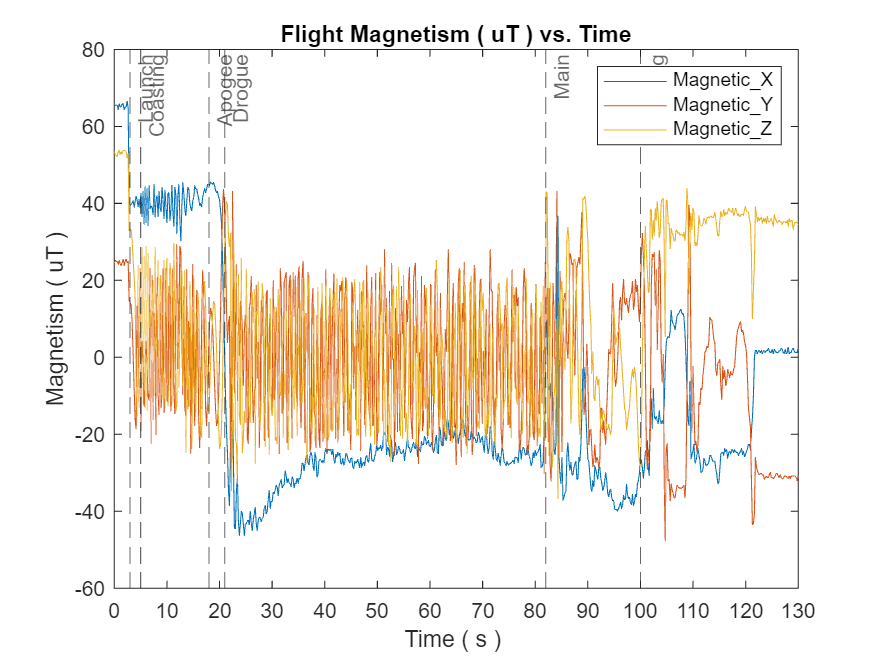

ZoomMagnetPlot = plot(AtmoTable, "Time", ["Magnetic_X", "Magnetic_Y", "Magnetic_Z"]);
title("Flight Magnetism ( uT ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Magnetism ( uT )")
xticklabels(0:10:150)
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

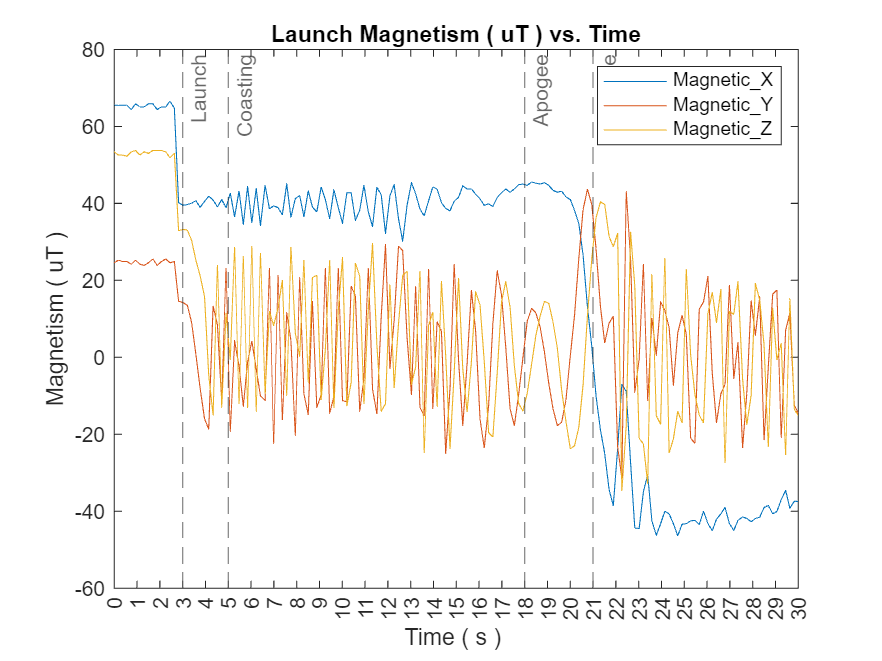

LaunchMagnetPlot = plot(AtmoTable, "Time", ["Magnetic_X", "Magnetic_Y", "Magnetic_Z"]);
title("Launch Magnetism ( uT ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Magnetism ( uT )")
xticklabels(0:30)
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

#### Acceleration (m/s^2) vs Time

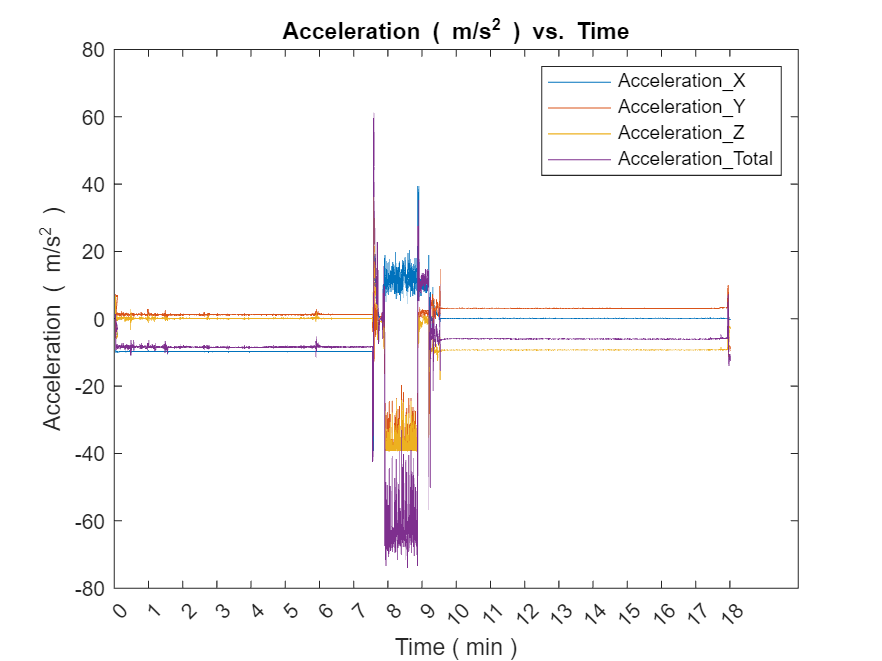

AccelTotalPlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z", "Acceleration_Total"]);
title("Acceleration ( m/s^2 ) vs. Time")
ylabel("Acceleration ( m/s^2 )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

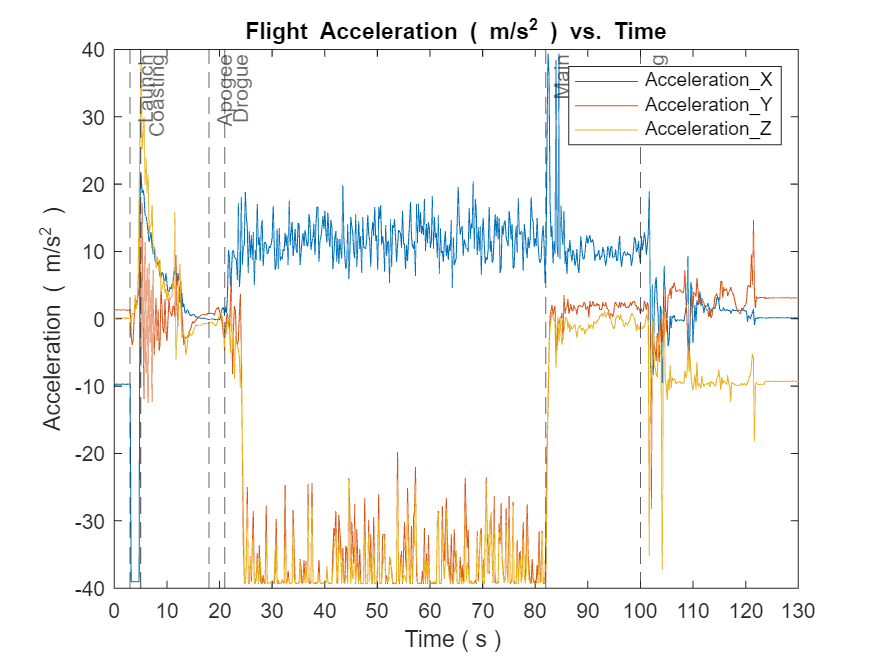

ZoomAccelTotalPlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z"]);
title("Flight Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

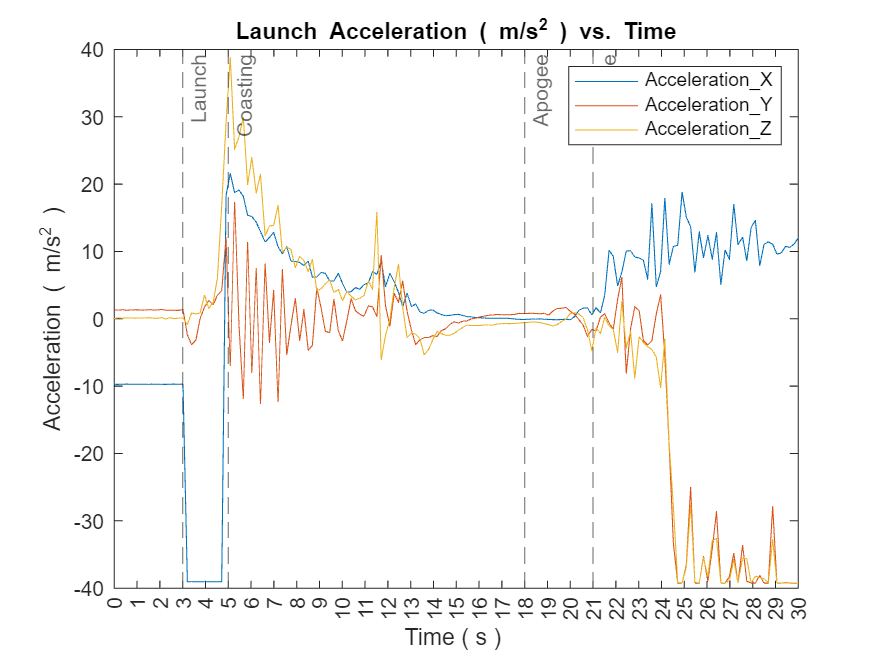

AccelPlot = plot(AtmoTable, "Time", ["Acceleration_X", "Acceleration_Y", "Acceleration_Z"]);
title("Launch Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

Acceleration X

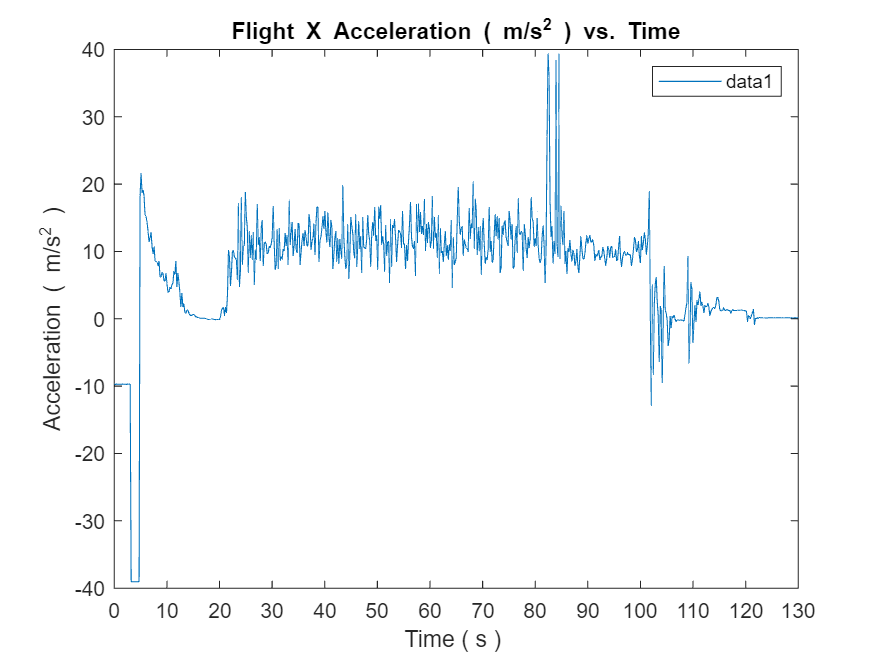

AccelXPlot = plot(AtmoTable, "Time", "Acceleration_X");
title("Flight X Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

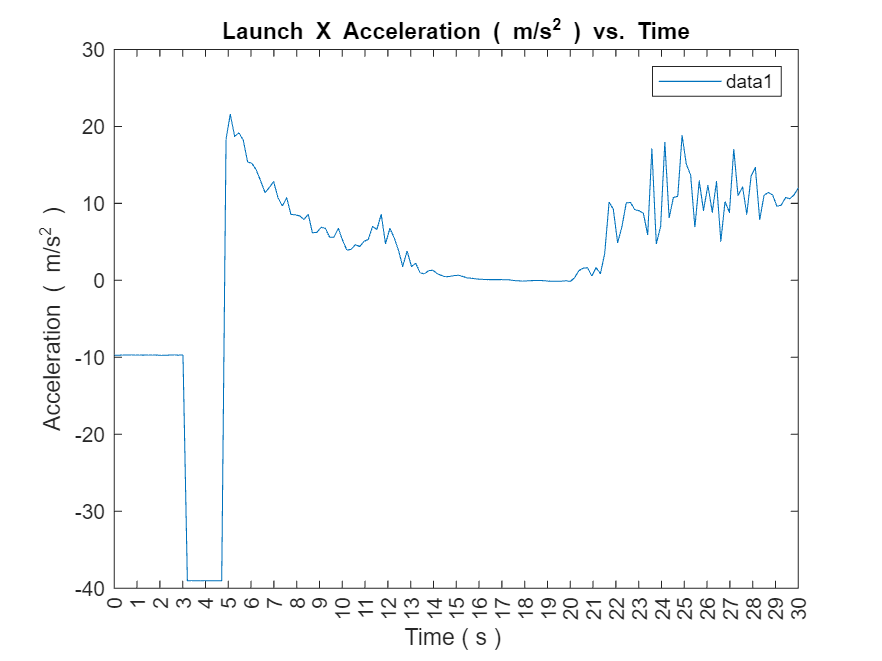

UpwardAccelXPlot = plot(AtmoTable, "Time", "Acceleration_X");
title("Launch X Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

Acceleration Y

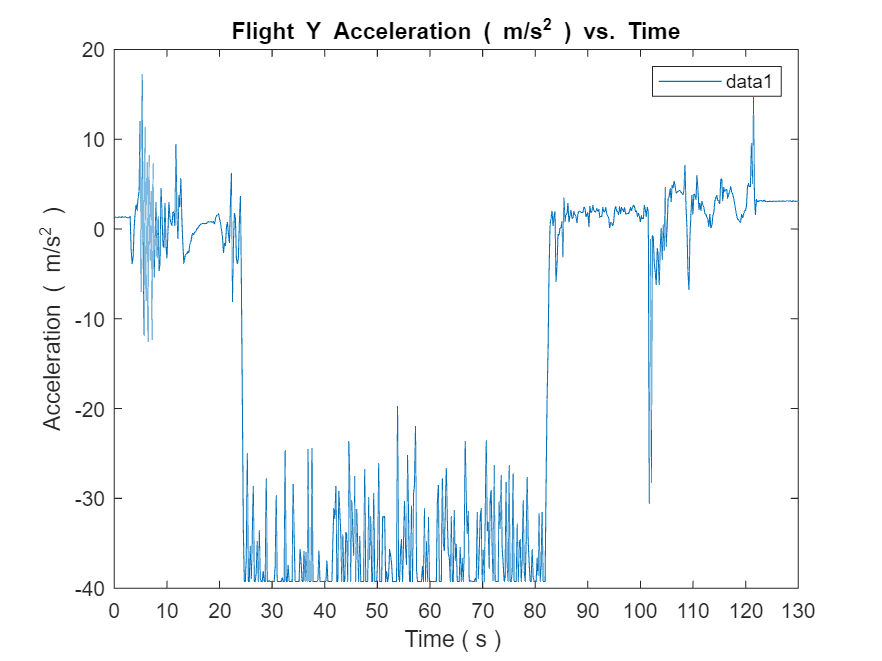

AccelYPlot = plot(AtmoTable, "Time", "Acceleration_Y");
title("Flight Y Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

Acceleration Z

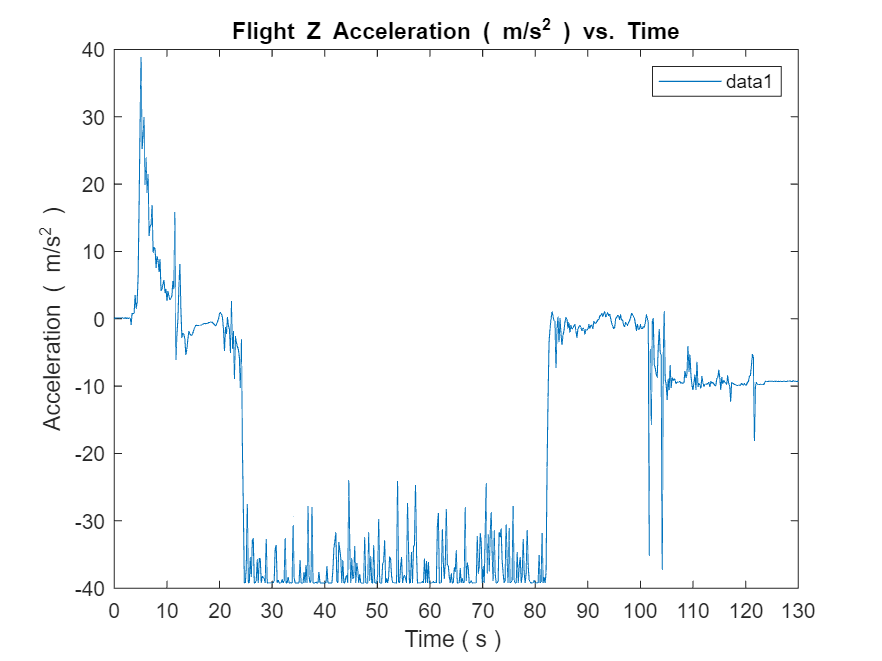

AccelZPlot = plot(AtmoTable, "Time", "Acceleration_Z");
title("Flight Z Acceleration ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration ( m/s^2 )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

#### Gravity (m/s^2) vs Time

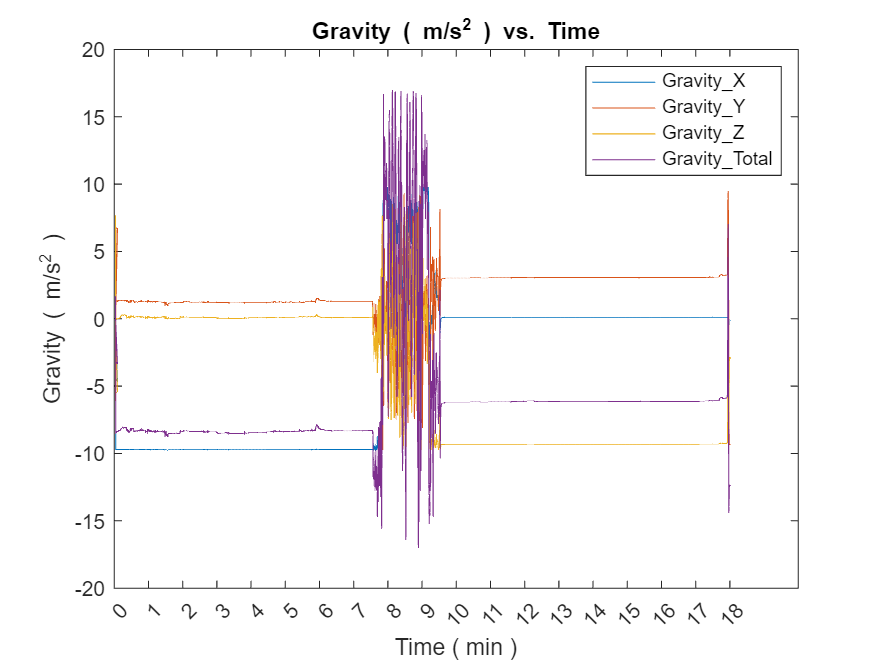

GravPlot = plot(AtmoTable, "Time", ["Gravity_X", "Gravity_Y", "Gravity_Z", "Gravity_Total"]);
title("Gravity ( m/s^2 ) vs. Time")
ylabel("Gravity ( m/s^2 )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

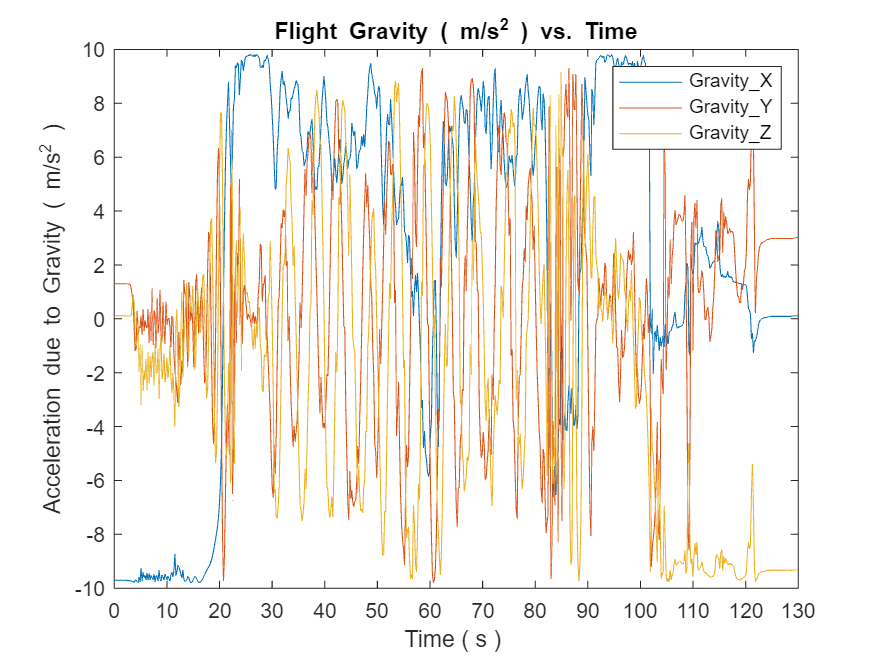

ZoomGravPlot = plot(AtmoTable, "Time", ["Gravity_X", "Gravity_Y", "Gravity_Z"]);
title("Flight Gravity ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration due to Gravity ( m/s^2 )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

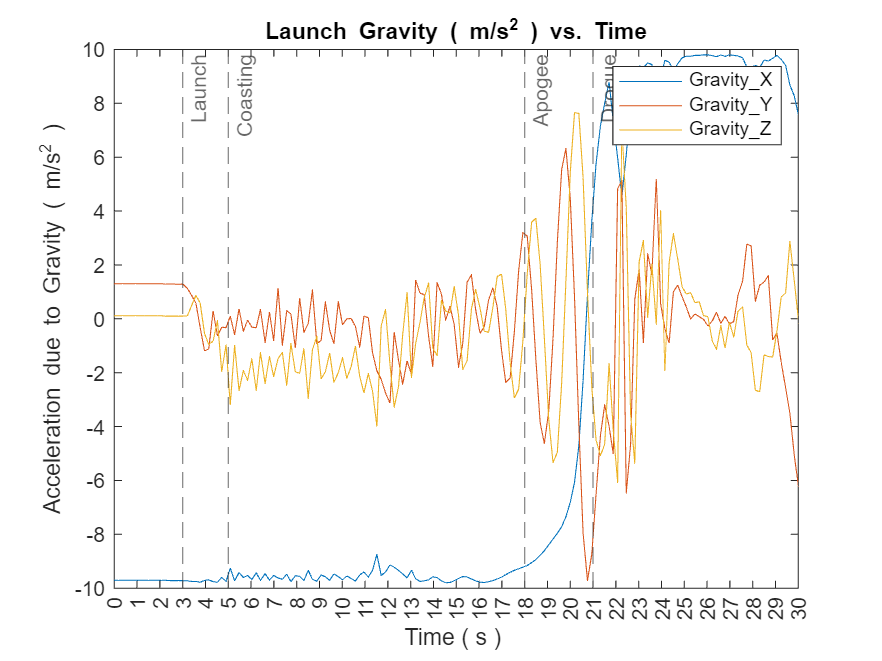

LaunchGravPlot = plot(AtmoTable, "Time", ["Gravity_X", "Gravity_Y", "Gravity_Z"]);
title("Launch Gravity ( m/s^2 ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Acceleration due to Gravity ( m/s^2 )")
xline(453000, "--", "Launch", 'HandleVisibility','off');
xline(455000, "--", "Coasting", 'HandleVisibility','off');
xline(468000, "--", "Apogee", 'HandleVisibility','off');
xline(471000, "--", "Drogue", 'HandleVisibility','off');
xline(532000, "--", "Main", 'HandleVisibility','off');
xline(550000, "--", "Landing", 'HandleVisibility','off');
xticklabels(0:30)
xlim([450000,480000]);
xticks([450000:1000:480000])
legend

#### Position (m) vs Time

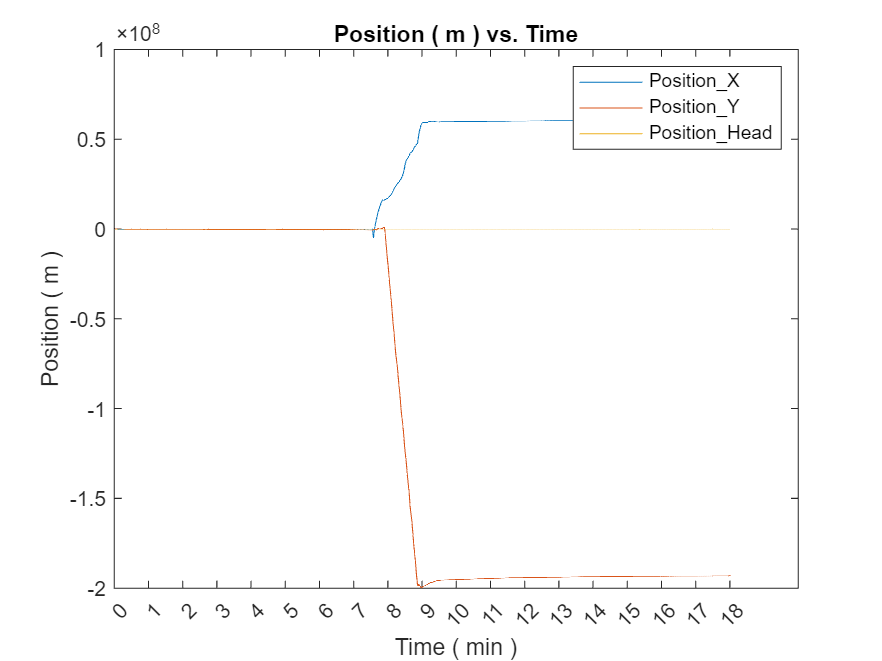

PositionPlot = plot(AtmoTable, "Time", ["Position_X", "Position_Y", "Position_Head"]);
title("Position ( m ) vs. Time")
ylabel("Position ( m )")
xlabel("Time ( min )")
xticklabels([0:18])
xticks([0:60000:AtmoTable{5741, "Time"}])
legend

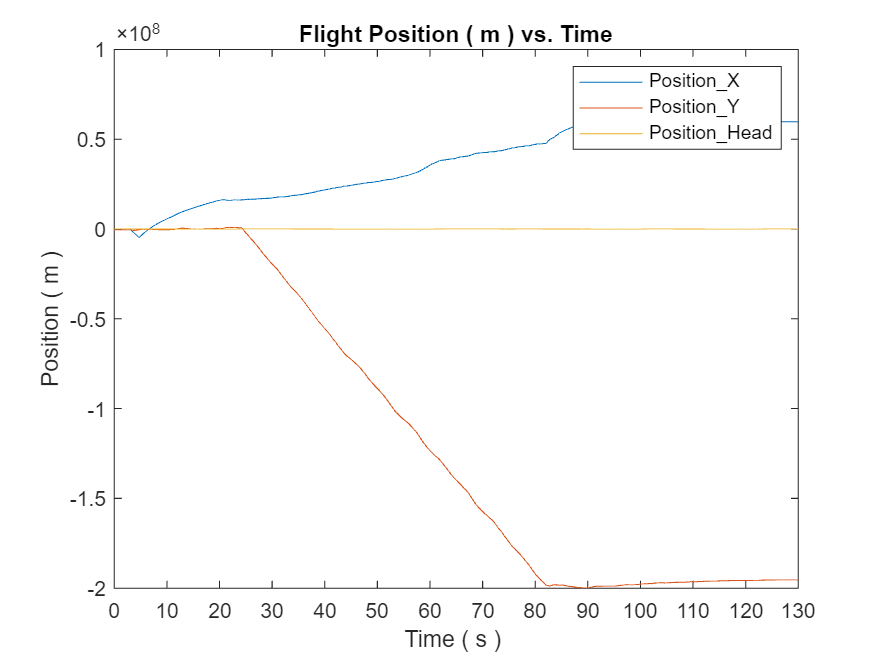

ZoomPositionPlot = plot(AtmoTable, "Time", ["Position_X", "Position_Y", "Position_Head"]);
title("Flight Position ( m ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Position ( m )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])
legend

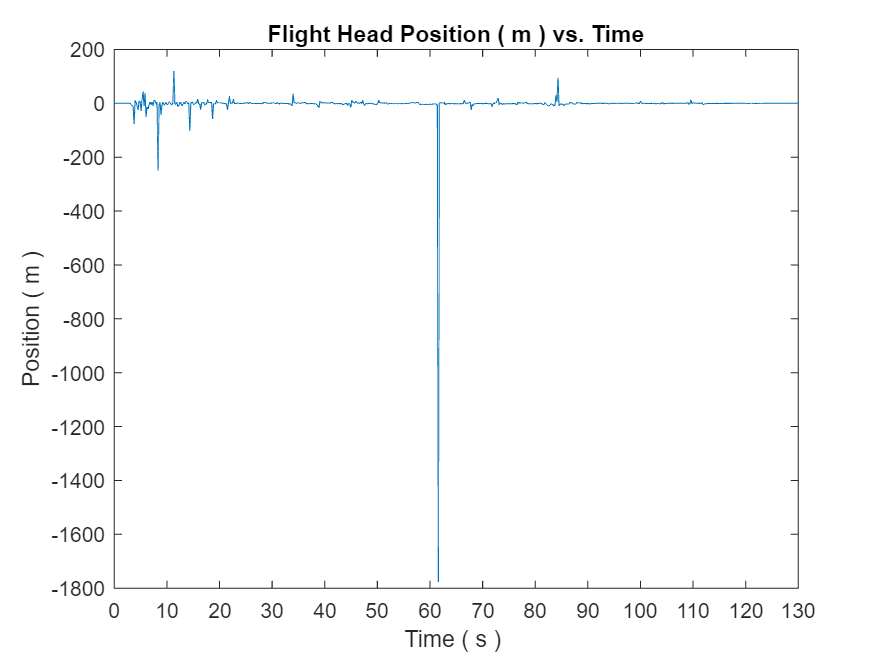

ZoomHeadPositionPlot = plot(AtmoTable, "Time", "Position_Head");
title("Flight Head Position ( m ) vs. Time")
xlabel("Time ( s ) ")
ylabel("Position ( m )")
xticklabels(0:10:150)
xlim([450000,580000]);
xticks([450000:10000:580000])